# FILTRO DE KALMAN PARA FILTRAR UNA SEÑAL RUIDOSA

sEn este ejemplo se utiliza el filtro de Kalman para estimar una señal a partir de mediciones (datos) contaminados con ruido

Modelo del sistema:


$$x(k+1)=F*x(k)+w(k)\\
z(k)=H*x(k)+v(k)$$


donde:

$x(k)$: Señal vedadera (estado)

$z(k)$: medición ruidosa

$w(k)$: ruido de proceso ~ N(0,Q)

$v(k)$: ruido de medición

## Simulacion para obtener datos

%% PARÁMETROS DE LA SIMULACIÓN
N = 200;              % Número de muestras
dt = 0.1;             % Paso de tiempo

% Covarianzas del filtro
Q = 1e-3;             % Ruido de proceso
R = 0.25;             % Ruido de medición
% GENERACIÓN DE LA SEÑAL VERDADERA
t = (0:N-1) * dt;
x_real = sin(0.5*t) + 0.3*cos(2*t);
% GENERACIÓN DE MEDICIONES RUIDOSAS
sigma_v = sqrt(R);
z = x_real + sigma_v*randn(1,N);

## Inicializacion del Filtro de Kalman

% Estado inicial
x_est = 0;

% Covarianza inicial (alta incertidumbre)
P = 1;

% Matrices del sistema (modelo escalar)
F = 1;    % x(k+1) = F * x(k)
H = 1;    % z(k)   = H * x(k+1)

% Almacenamiento
x_t = zeros(1,N);
P_t = zeros(1,N);
K_t = zeros(1,N);

## Filtro de Kalman

for k = 1:N
    
    %-------------------------------------------------------------
    % 1. PREDICCIÓN
    %-------------------------------------------------------------
    x_pred = F * x_est;
    P_pred = F * P * F' + Q;
    
    %-------------------------------------------------------------
    % 2. ACTUALIZACIÓN
    %-------------------------------------------------------------
    % Innovación
    innov = z(k) - H * x_pred;
    
    % Ganancia de Kalman
    S = H * P_pred * H' + R;
    K = P_pred * H' / S;
    
    % Corrección
    x_est = x_pred + K * innov;
    
    % Actualización de la covarianza
    P = (1 - K * H) * P_pred;
    
    % Guardar resultados
    x_t(k) = x_est;
    P_t(k) = P;
    K_t(k) = K;
end

## Metricas de desempeño

rmse_medicion = sqrt(mean((z - x_real).^2));
rmse_filtrado = sqrt(mean((x_t - x_real).^2));

fprintf('RMSE medición ruidosa : %.4f\n', rmse_medicion);

RMSE medición ruidosa : 0.5006


fprintf('RMSE señal filtrada   : %.4f\n', rmse_filtrado);

RMSE señal filtrada   : 0.4323


## Graficas de resultados

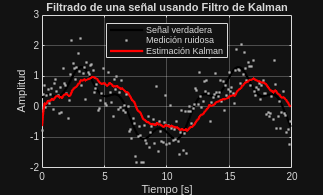

%% GRÁFICA PRINCIPAL
figure;
plot(t, x_real, 'k', 'LineWidth', 2); hold on;
plot(t, z, '.', 'Color', [0.7 0.7 0.7]);
plot(t, x_t, 'r', 'LineWidth', 2);
grid on;
xlabel('Tiempo [s]');
ylabel('Amplitud');
title('Filtrado de una señal usando Filtro de Kalman');
legend('Señal verdadera', 'Medición ruidosa', 'Estimación Kalman', ...
       'Location', 'best');

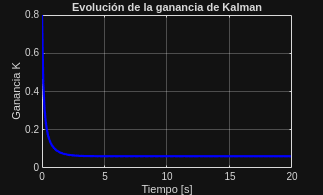


% EVOLUCIÓN DE LA GANANCIA DE KALMAN
figure;
plot(t, K_t, 'b', 'LineWidth', 2);
grid on;
xlabel('Tiempo [s]');
ylabel('Ganancia K');
title('Evolución de la ganancia de Kalman');

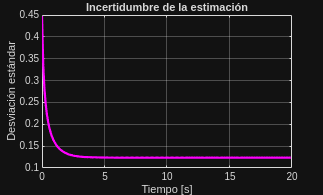


% INCERTIDUMBRE DE LA ESTIMACIÓN
figure;
plot(t, sqrt(P_t), 'm', 'LineWidth', 2);
grid on;
xlabel('Tiempo [s]');
ylabel('Desviación estándar');
title('Incertidumbre de la estimación');